## 第一小组：

## 基于MatLab的遗传算法入门——解决背包问题

组员：

        卿云帆

        王大卫

        周宇凡

        徐真志

## 背包问题

背包问题最经典的场景就是“小偷偷取东西”，在小偷背包（**capacity**）容量有限的请况下，如何在众多重量（**W**）价值（**V**）不同的货物中，选取总价值最高的组合。

具体来说，背包问题可分为三种：0-1背包，完全背包，多重背包。

- `0-1背包：每种货物只能有一件`

- `完全背包：每种货物的数量无限`

- `多重背包：每种货物数量（``N``）为给定的有限值。`

这里，我们以0-1背包为例，来做GA算法的讲解。

解决背包问题传统采用**穷举法**和**动态规划**。

**Example:**

        背包容量：10

        6件物品

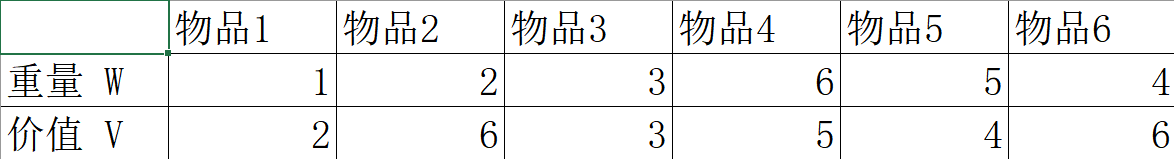

capacity = 10

capacity = 10

Weight = [1 2 3 6 5 4]

Weight =      1     2     3     6     5     4


Value = [2 6 3 5 4 6]

Value =      2     6     3     5     4     6


%whos

一、穷举法解决0-1背包

                        "***Brute force*** ***attacks*** ***always work*****"**

        穷举法：最朴素的解决问题思想，理论上讲，穷举法几乎能解决         

                       一切问题。

        这里我们分别考虑背包里装1件，2件，3件...6件的所有可能情

        况，并计算所有可能情况的最大值。

things=1:6;

maxValue=0;
maxComb=[];
%分别考虑装1，2，3...6
%doc nchoosek
for i = things
    combination=nchoosek(things,i)
    %combination矩阵，每行代表一个组合

    for row = 1:size(combination)
        tmpV=0;
        tmpW=0;
        t=combination(row,:);
        for elem=t
            tmpW=tmpW+Weight(elem);
            tmpV=tmpV+Value(elem);            
        end
        if tmpW<=capacity && tmpV>maxValue
            maxValue=tmpV;
            maxComb=Weight(t);
        end
    end
end

combination =      1
     2
     3
     4
     5
     6


combination =      1     2
     1     3
     1     4
     1     5
     1     6
     2     3
     2     4
     2     5
     2     6
     3     4


combination =      1     2     3
     1     2     4
     1     2     5
     1     2     6
     1     3     4
     1     3     5
     1     3     6
     1     4     5
     1     4     6
     1     5     6


combination =      1     2     3     4
     1     2     3     5
     1     2     3     6
     1     2     4     5
     1     2     4     6
     1     2     5     6
     1     3     4     5
     1     3     4     6
     1     3     5     6
     1     4     5     6


combination =      1     2     3     4     5
     1     2     3     4     6
     1     2     3     5     6
     1     2     4     5     6
     1     3     4     5     6
     2     3     4     5     6


combination =      1     2     3     4     5     6



maxValue

maxValue = 17

maxComb

maxComb =      1     2     3     4


穷举法思路十分简单易懂，就是列举出所有可行的组合方式进行计算，算法实现也并不复杂，只用循环和判断就可以解决·。

但在有限时间和有限算力的限制下，穷举法并不友善，当问题规模扩大，就无法利用穷举法去解决问题，一种想法是利用分支限界等方法进行剪枝，减少组合的可能性，当然除此以外，我们也可以用其他算法来解决

一种经典的解决办法就是——动态规划

二、经典动态规划解决0-1背包

*** “Solving Big Problems by Solving Little Problem ”***

考虑对 {N,capacity=C} 问题的求解,可以拆分为较小的两个问题，对于具体的第k件物体，无非只有两种可行的选择，选他 和 不选他。

即                {N,C}=max(  {(N-k),C },  {N,C-Wk}+Vk  )

从这样一个基本的想法入手，我们通过依次考虑物品和背包的更小的问题，可以得到最终的答案。我们将该问题转变为了某种意义上的填表问题

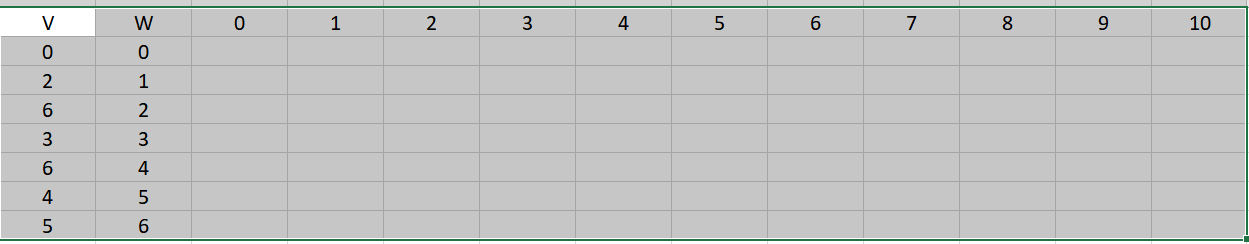

dp[i][j] 代表考虑i个物品，背包capacity=j时的最优解

                    dp[i][j] = max(dp[i-1][j] , dp[i-1][j-weight[i]]+value[i] )

                    注意条件(i>0才能使用递推，j-weight[i] >=0 时才能使用）

[Weight,idx]=sort(Weight);
Value=Value(idx);
Weight=[0,Weight]

Weight =      0     1     2     3     4     5     6


Value=[0,Value]

Value =      0     2     6     3     6     4     5


dp=zeros(7,11)

dp =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


for i = 2:7
    for j = 1:11
        if j-Weight(i)>=1
            %背包空间可以考虑该物品
            dp(i,j)=max(dp(i-1,j),dp(i-1,j-Weight(i))+Value(i));
        else
            %背包空间不足以考虑该物
            dp(i,j)=dp(i-1,j);
        end
        
    end
    dp
end

dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     2     6     8     8     8     8     8     8     8     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     2     6     8     8     8     8     8     8     8     8
     0     2     6     8     8     9    11    11    11    11    11
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     2     6     8     8     8     8     8     8     8     8
     0     2     6     8     8     9    11    11    11    11    11
     0     2     6     8     8     9    12    14    14    15    17
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     2     6     8     8     8     8     8     8     8     8
     0     2     6     8     8     9    11    11    11    11    11
     0     2     6     8     8     9    12    14    14    15    17
     0     2     6     8     8     9    12    14    14    15    17
     0     0     0     0     0     0     0     0     0     0     0


dp =      0     0     0     0     0     0     0     0     0     0     0
     0     2     2     2     2     2     2     2     2     2     2
     0     2     6     8     8     8     8     8     8     8     8
     0     2     6     8     8     9    11    11    11    11    11
     0     2     6     8     8     9    12    14    14    15    17
     0     2     6     8     8     9    12    14    14    15    17
     0     2     6     8     8     9    12    14    14    15    17


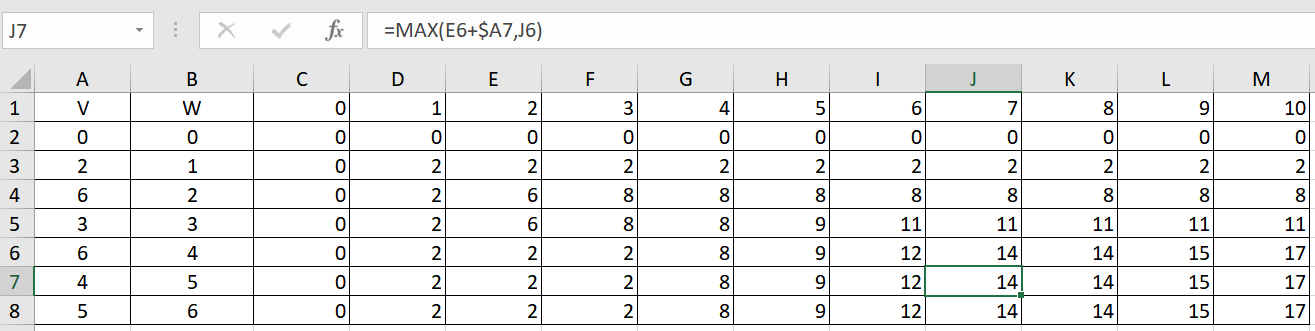

通过动态规划，我们将问题的复杂度从穷举的2^n降低到了n*capacity层次，让问题能得到更好的解决。

但如果我们考虑更多的物品(n)，更大的背包(capacity),n*capacity仍然是一个极大的开销。

事实上，0-1背包问题被证明是一个NP问题（非确定性多项式时间可解），也就是说，实际上，在比较大的问题规模下，我们很难在一定的时间内给出精确解，因此我们需要一些办法，在可接受的时间复杂度内得到一个足够好的近似解——遗传算法。

三、遗传算法

                                       "***Survival of the fittest ”***

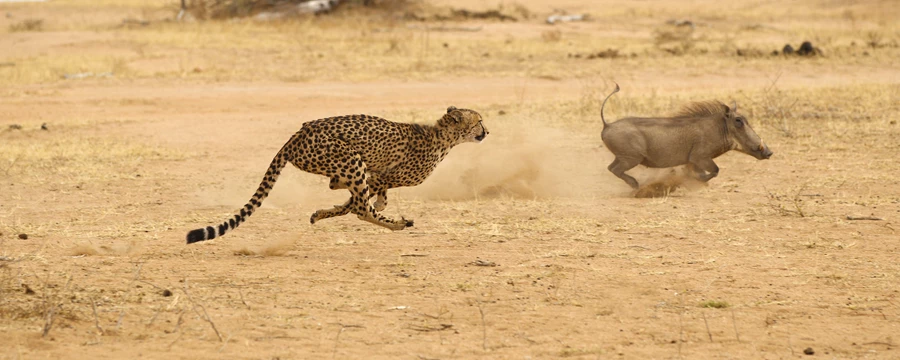

自然是如何挑选出一个”好“的种群的？

过度繁殖，生存斗争（也叫生存竞争），遗传和变异，适者生存。

 通过遗传算法解决问题的一般步骤

**1.编码**

        将问题表示为一个n位的二进制码，第i位表示物品i，数值为0表示物品没有选中，1表示选中物品。

**2.创建种群**

        种群是个体的集合

**3.表达适应度**

        适应度在0-1背包问题中表示的是背包中的总价值的大小，总价值越大个体的适应度越大。

**4.根据适应度进行选择**

        从种群中选出部分个体之后进行重组或交叉，产生的新个体依据适应度函数进行优胜劣汰，选出优良个体。

**5.交叉：交换良好适应度个体的部分片段**

        不同的个体之间随机的进行杂交，其基因进行再次重组。其后产生新的具有不同适应度的新个体。

**6.变异：在子代中产生随机变换**

        不同的个体之间随机的进行杂交，其基因进行再次重组。其后产生新的具有不同适应度的新个体。

通俗的说，我们将问题的解用二进制表示出来，并将众多的解组成一个解的集合，他们的价值总和作为适应度，通过 组合不同解生成新的部分 变异当前解生成新的解  淘汰适应度低的解，不断迭代来促进种群“进化”从而得到一个近似解。

解决背包问题：

0.问题初始化

n=50  %50个物品

n = 50

W=[80 82 85 70 72 70 66 50 55 25 50 55 40 48 50 32 22 60 30 32 ...
    40 38 35 32 25 28 30 22 50 30 45 30 60 50 20 65 20 25 30 10 ...
    20 25 15 10 10 10 4 4 2 1];       %各个物品的重量，50个个体
V=[220 208 198 192 180 180 165 162 160 158 155 130 125 122 120 ...
    118 115 110 105 101 100 100 98 96 95 90 88 82 80 77 75 73 72 ...
    70 69 66 65 63 60 58 56 50 30 20 15 10 8 5 3 1];     %各个物品的价值，50个个体
CW=1000;   %背包大小 可容纳的总重量



1.设置初始群体

popsize=1000            %种群大小

popsize = 1000


popbest=zeros(popsize, n)   %最优种群存储对象

popbest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


pop=initpop(popsize,n) %初始种群initpop.m

pop =      0     1     0     0     1     0     1     0     1     0     0     1     1     0     0     1     1     1     1     0     1     0     0     1     0     1     1     0     1     1     0     1     0     0     0     1     1     0     1     0     0     0     0     0     1     0     0     1     1     0
     0     0     0     1     0     0     1     0     0     1     1     1     1     0     0     0     1     0     1     0     0     1     1     1     1     1     1     0     0     0     1     0     0     1     0     1     1     0     0     1     1     1     0     1     1     0     0     1     1     1
     1     0     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     1     1     0     0     1     0     0     1     0     0     0     0     1     0     0     1     0     1     0     0     0     1     0     0     0     0     0     0     0     1     0     0     1
     1     0     0     0     1     0     0     0     1     0     0     0     0     0     0 


t=1000                  %迭代次数

t = 1000


pc=0.9                  %交叉率

pc = 0.9000

pm=0.05;                %变异率

%记录每一次迭代的种群最适应的个体(后面画图）
y=zeros(1,popsize);   %记录最大价值
g=zeros(1,popsize);   %记录最大重量
n=zeros(1,popsize);   %记录位置

2.迭代计算

for i=1:1000
    
    [fitvalue]=calobjvalue(pop,V,W,CW); %计算目标函数
                                        %对应 对环境适应度衡量
    
    [bestweight,bestvalue, bestpop]=best(pop,fitvalue,W); 
    %计算最优个体重量，价值，和位置
    
    y(i)=max(bestvalue);    %记录最大价值
    
    g(i)=max(bestweight);   %记录最大重量
    
    n(i)=i;                 %记录位置
    
    popbest(i,:)=bestpop;    %记录最优个体                                    
                                        
    
    
    [newpop]=selection(pop,fitvalue);  %进行选择计算
                                       %对应  找到有生育权的个体     
     
                                       
    [newpop1]=crossover(newpop,pc);    %进行交叉计算
                                       %对应  基因交换
                                       
    [newpop2]=mutation(newpop1,pm);     %进行变异计算
                                        %对应 基因突变
                                      
 

    pop=newpop2;   %迭代重复
end
pop

pop =      0     1     1     0     0     1     0     1     1     1     1     0     1     0     1     0     1     0     1     1     0     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     1     0     0     1     0     0     1
     0     1     1     1     0     1     0     1     1     1     1     0     1     0     1     0     1     0     1     1     0     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     1     0     0     1     0     0     1
     0     1     1     0     0     1     0     1     1     1     1     0     1     0     1     1     1     0     1     1     0     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     1     0     0     1     0     0     1
     0     1     1     0     0     1     0     1     1     1     1     0     1     0     1 

3.图像可视化

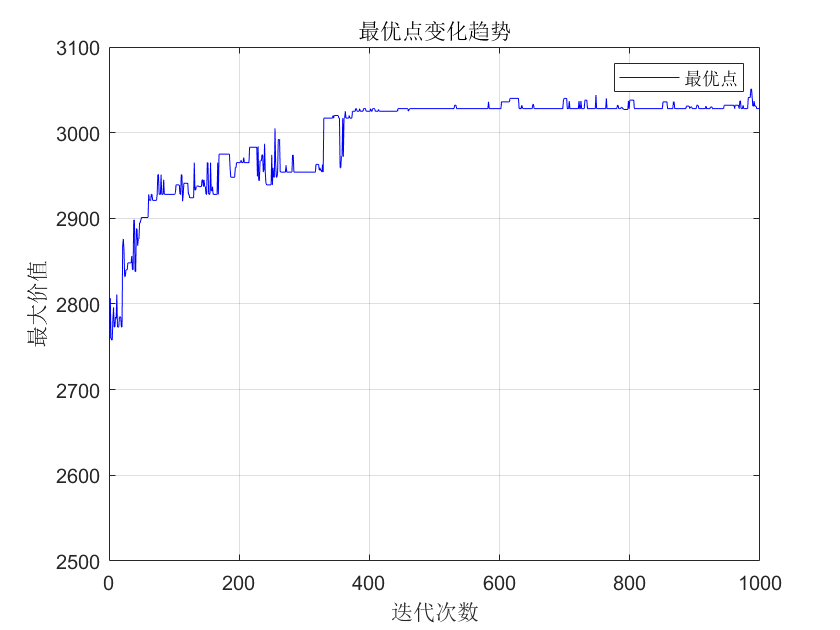

i=1:1000;
plot(y(i),'-b')
xlabel('迭代次数')
ylabel('最大价值');
title('最优点变化趋势');
legend('最优点');
grid on

xlim([0 1000])
ylim([2500 3100])


[z, index]=max(y);
po=n(index)         %最优代数位置

po = 986

W=g(index)         %最优重量

W = 996

V=z                %最优价值

V = 3051

BEST=popbest(po,:)    %最优解

BEST =      1     1     0     0     0     1     0     1     1     1     1     0     1     1     1     1     1     0     1     1     1     1     0     1     1     1     1     1     0     1     0     1     0     0     1     0     1     0     0     1     0     0     0     0     0     0     1     0     0     1


总结：

一：实时的看到代码运行过程和结果，不用变换窗口

二：分节执行，方便一步步地调试，定位代码错误

三：方便添加文本、注释等，便于阅读